# Acquire relaxation constant kr 

folder = "lattice_calibration_data/15x15x15/trial4/";
index4 = ['1';'2'];

% x*kr = y, find kr
x = [];
y = [];
counter = 1;

for iter=1:size(index4,1)
    load(folder + "lattice_data_" + index4(iter));
    t = t_biased;
    fz_fil = lowpass(fz,0.1);
    z_fil = lowpass(z,0.00001,100);
    v = diff(z_fil)*100;
    v(end + 1) = v(end);
    v_fil = lowpass(v,0.00000001,100);
    dfz = diff(fz_fil)*100;
    dfz(end+1) = dfz(end);
    dfz_fil = lowpass(dfz,0.1);
    v0 = 2e-4;
    t_movs = [];
    i_movs = [];
    i = 1;
    t_counter = 1;

    length = size(v_fil,1);

    while true
        if i>length
            break;
        end
        if abs(v_fil(i)) > v0
            t_movs(t_counter) = t(i-5);
            i_movs(t_counter) = i-5;
            t_counter = t_counter + 1;
            i = i+1;
            while abs(v_fil(i)) > v0
                i = i+1;
            end
            t_movs(t_counter) = t(i-1);
            i_movs(t_counter) = i-1;
            t_counter = t_counter + 1;
            i = i+1;
        else
            i = i+1;
        end
    end
    i_movs = i_movs';

    % t_movs = t_movs';
    % fz_movs = fz_fil(i_movs);
    % dfz_movs = dfz_fil(i_movs);
    
    % plot(t,fz_fil,"LineWidth",1.5,"Color","green");
    % hold on;
    % scatter(t_movs,fz_movs,20,"red","filled");
    % grid on;
    % hold off;
    % 
    % plot(t,dfz_fil,"LineWidth",1.5,"Color","green");
    % hold on;
    % scatter(t_movs,dfz_movs,20,"red","filled");
    % hold off;

    id1 = (2:2:6)';
    id2 = (8:2:10)';
    di = 1*100;

    % the positive relaxations first
    n = size(id1,1);
    %goes through each relaxation
    for j=1:n
        % in relxation, sample at an offset of 1s
        dfz0 = dfz_fil(i_movs(id1(j)));
        for k=1:5
            dfztr = dfz_fil(i_movs(id1(j)) + di*k);
            x(counter) = di*k/100;
            y(counter) = log(dfz0/dfztr);
            counter=counter+1;
        end
    end

    % the negative relxations next
    n = size(id2,1);
    %goes through each relaxation
    for j=1:n
        % in relxation, sample at an offset of 1s
        dfz0 = dfz_fil(i_movs(id2(j)));
        for k=1:5
            dfztr = dfz_fil(i_movs(id2(j)) + di*k);
            x(counter) = di*k/100;
            y(counter) = log(dfz0/dfztr);
            counter=counter+1;
        end
    end
end

scatter(x,y,20,"yellow","filled");
hold on;
xlim([0,7]);
ylim([0,7]);
kr = y*x'/(x*x');
x_axis = linspace(0, 10, 100);
plot(x_axis, kr * x_axis, "LineWidth", 1.5, "Color", "red");
disp("Kr : " + num2str(kr));

Kr : 0.85363


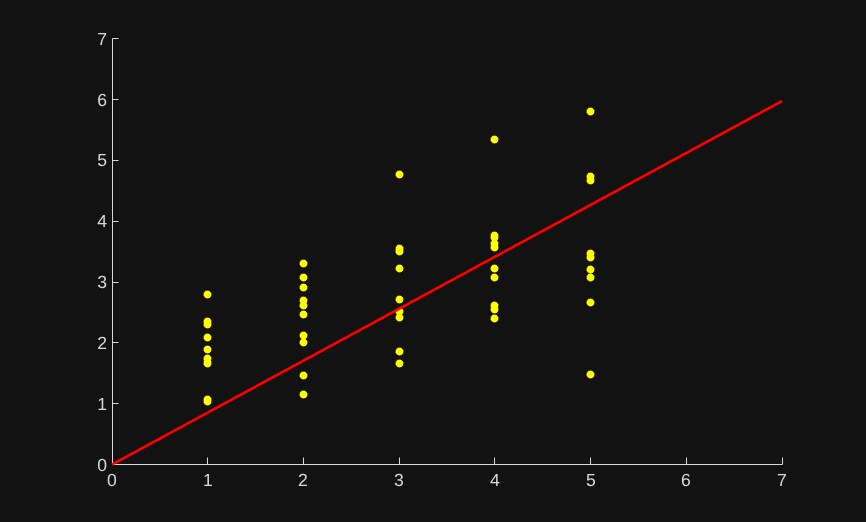

hold off